# 円筒動画作成

## Path

環境に応じて変更

% ディレクトリ
dir = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/研究/221208/';
% データファイル名
file_name = '01.csv';
% ゲージファイル名
gagefile_name = 'gage.xlsx';
% 書き出しビデオ名
video_name = '01.mp4';

## データ読込

基本変更しない

data_dir = append(dir,file_name);
gage_dir = append(dir,gagefile_name);
video_dir = append(dir,video_name);
% データ
data1 = readmatrix([data_dir]);
% gage
gage = readmatrix([gage_dir]);

## 変数

視点・終点 :  gageファイルの3列目に始点と終点の列数を記入

% 巻き数
m = 15;

% 始点
gage1 = gage(1, 3);

% 終点
gage2 = gage(15, 3);

% 巻きの高さ
H = 70;

## データ整理

基本変更しない

% データ数
n = gage2 - gage1 + 1;
% データ
Z = data1(6:end, gage1:gage2) * (-1);
% データサイズ
sz = size(Z);
row = sz(1);
% プロット位置
theta = linspace(0, 2 * m * pi, n);
x = 50 * cos(theta);
y = 50 * sin(theta);
h = linspace(H, 0, n);
t = linspace(0, (row - 0.01) / 100, row);
% colorbar用
zmax = max(max(Z));
zmin = min(min(Z));
zmean = mean(Z);
zstd=rms(Z);
zmin=zmean-2 * zstd;
zmax=zmean+2 * zstd;

a=linspace(1,1628,15)

a = 1.0e+03 *

    0.0010    0.1172    0.2334    0.3496    0.4659    0.5821    0.6983    0.8145    0.9307    1.0469    1.1631    1.2794    1.3956    1.5118    1.6280


a=round(a)

a =            1         117         233         350         466         582         698         815         931        1047        1163        1279        1396        1512        1628


for i = 1:14
    z{i}=Z(:,a(i):a(i+1)-1);
end

ans = 9.8500

for j = 1:116
    for k = 1:14
        x{j}(:,k)=z{k}(:,j);
    end
end

for l = 1:14
    f=diff(x{l},[],2);
    [F,I{l}]=max(f,[],2);
end

I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


I = 1×14 の cell 配列
    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}    {2009×1 double}


X = 50 * cos(theta);
Y = 50 * sin(theta);
H = linspace(H, 0, n);

for l=1:14
    I{l}(1922,:)
end

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

ans = 10

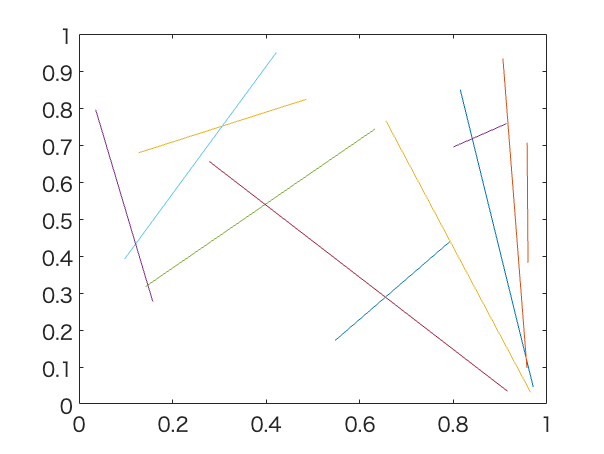

N = 11;
p_x = rand(N,1);
p_y = rand(N,1);
q_x = rand(N,1);
q_y = rand(N,1);
figure(1)
for ii=1:N
    plot([p_x(ii),p_y(ii)],[q_x(ii),q_y(ii)])
    hold on
end
hold off

## 動画セクション

基本変更しない

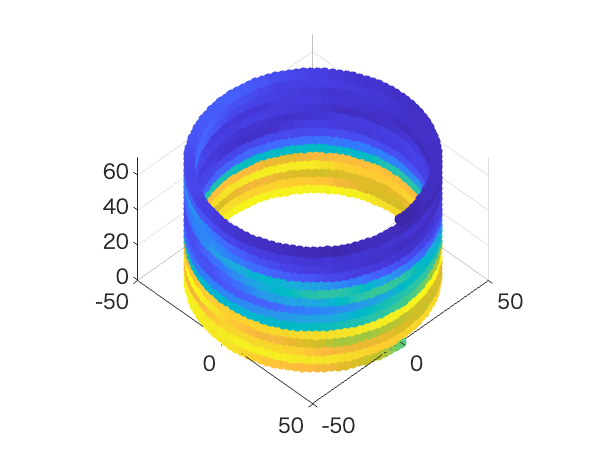

T = 0.01:0.01:row / 100;
for i = 1:length(T)
    z{i} = Z(i,:);
end
fig = figure; % Figure オブジェクトの生成
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
zlim([0 75]);
frames(row) = struct('cdata', [], 'colormap', []); % 各フレームの画像データを格納する配列
H=scatter3(x, y, h, [], z{1}, 'filled');
view(45, 45)
daspect([1 1 1])

% for i = 1:row
%     set(H, 'CData', z{i});
%     clim([-20 50]);
%     drawnow;
%     frames(i) = getframe(fig);
% end
% video = VideoWriter(video_dir, 'MPEG-4');
% video.FrameRate = 100;
% open(video);
% writeVideo(video, frames);
% close(video);
% 